# **Particle in Cell code**

This Live Script was developed in order to understand the particle-in-cell method. The quantities of the code are not physical since the aim of this document is visualize each step of the method. The code is based on the work of [Giovanni Lapenta](https://wis.kuleuven.be/CmPA/staff-members-test/00052182) from K.U.Leuven.

**Variables**

- L: Length of the system.

- dt: Time step.

- Nt: Number of time steps.

- Ng: Grid points.

- WP: Plasma frequency.

- N1: Number of particles.

- V01: Mean velocity.

- Vth1: Thermal velocity.

- QM1: Charge mass relation.

- XP1: Amplitude of the perturbation.

- Mode1: Mode of the perturbation.

The first step is to define the parameters of the code:

clear
L =  1;
dt = 0.5;
Nt = 1;
Ng = 6;
WP = 1;
dx = L/(Ng-1);

Then we will define the properties beam:

N1 =    5;
V01 =   0;
Vth1 =  0.1;
QM1 =   -1;
XP1 =   0;
Mode1 = 0;

Then we are going to define the charge of the super-particles and the background density:

Q1 = (WP^2)/(QM1*N1/L)

Q1 = -0.2000

rho_back = -N1*Q1/L

rho_back = 1

Now, the particles particles will be positioned along the x axis with a sinusoidal perturbation, taking into account that the code is one-dimesional. 

time = 0:dt:(Nt-1)*dt;
space = linspace(0,L,Ng);
xp1 = (linspace(0,L-L/N1,N1))'

xp1 =          0
    0.2000
    0.4000
    0.6000
    0.8000


xp1 = xp1 + XP1*(L/N1)*sin(2*pi*xp1/L*Mode1);

Then, we will give a velocity to the beam. In first palce we multiply the thermal velocity with the function `randn(NS,1)` which returns an NS-by-1 matrix of normally distributed random numbers. 

vp1 = Vth1*randn(N1,1);
vp1 = vp1 + V01

vp1 =    -0.0467
    0.0145
    0.0631
   -0.0277
   -0.1385


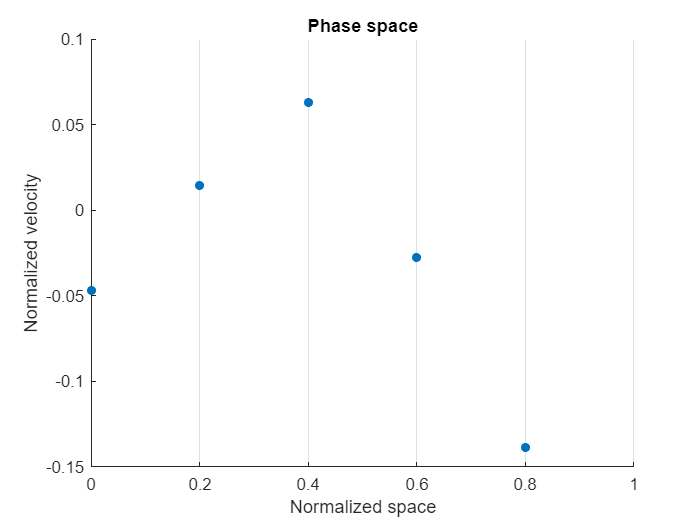

figure;
scatter(xp1,vp1,30,'filled')
title('Phase space')
xlabel('Normalized space')
ylabel('Normalized velocity')
xlim([0 L])
xticks(space)
ax = gca;
ax.XGrid = 'on';

ax.YGrid = 'off';

We can plot the histogram in order to see how particles are distributed.

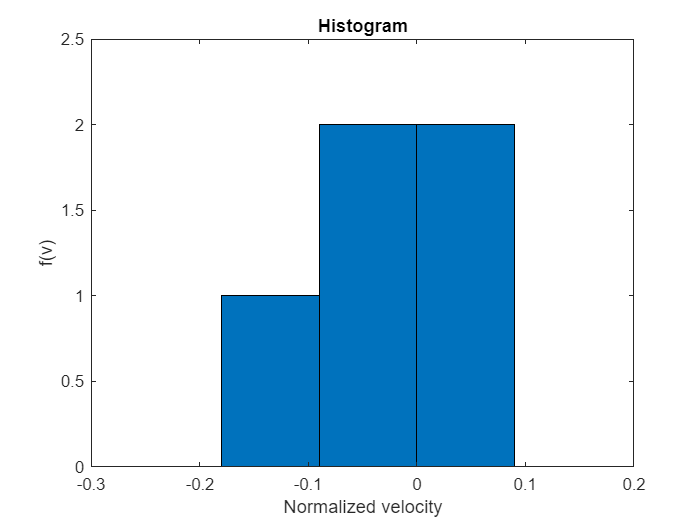

histfit([vp1])
title('Histogram')
xlabel('Normalized velocity')
ylabel('f(v)')

One way to taste the functionality of the code is to see the energy and the momentum conservation. Momentum is defined as:


$$P=\sum_pm_pv_p$$


The kinetic energy is:


$$E_k=\frac{1}{2}\sum_pm_pv_p^2$$


and the potential energy is:


$$E_p=\frac{1}{2}\epsilon_0\sum_g(E_g^2) dx$$


where $E_g$ is the field in the grid points.

Then we will prepare the vectors for momentum, kinetic energy and potential energy as:

mom = zeros(1, Nt); E_kin = zeros(1, Nt); E_pot = zeros(1, Nt);

In order to find the electric field, we need to solve the Poisson´s equation which is define as:


$$\nabla^2\phi=\frac{\rho}{\epsilon_0}$$


were $\phi$ is the electric potential. The Poisson’s equation can be discretized in 1D using the classic three point formula:


$$\epsilon_0\frac{\phi_{g+1}-2\phi_g+\phi_{g-1}}{dx^2}=-\rho_g$$


In this way we need to define a matrix with the coeficients that multiply $\phi$ wich will be $A_x$.


$$A_x\Phi=-\rho_gdx^2$$


Phi = 0; 
un = ones(Ng-1, 1);
Ax = spdiags([un -2*un un], [-1 0 1], Ng-1, Ng-1);

Then we observe the form of the matrix $A_x$:

full(Ax)

ans =     -2     1     0     0     0
     1    -2     1     0     0
     0     1    -2     1     0
     0     0     1    -2     1
     0     0     0     1    -2


The variable `mat1` is the interpolation function and `p1 `is an auxiliarity vector. We will explain later this variables.

mat1 = 0; Eg = 0;
p1 = 1:N1; p1 = [p1 p1];

## **Computational Cycle**

Now we are going to star with the comutational cycle

for it = 1:Nt

**Diagnostics**

In first place we will find out the momentum and the energy for each iteration

    mom(it) =  (Q1)*(sum(vp1));
    E_kin(it) = 0.5*abs(Q1)*(sum(vp1.^2));
    E_pot(it) = 0.5*sum(Eg.^2)*dx;

**Newton's equations: Updating the positions**

Then we will update positions. By Newton's equations we have:


$$\frac{dx_p}{dt}=v_p$$



$$\frac{dv_p}{dt}=\frac{q_s}{m_s}E_p$$


The Euler method will be used to dicretize the equations:


$$x_p^{n+1}=x_p^n+\Delta tv_p^{n+1}$$



$$v_p^{n+1}=v_p^{n}+\Delta t\frac{q_s}{m_s}E_p^{n+1}$$


Then we have:

    xp1 = xp1 + vp1*dt

xp1 =    -0.0234
    0.2073
    0.4316
    0.5862
    0.7307


**Periodic boundary conditions **

Now, applying the periodic boundary conditions:

- If xp1 is less than 0, then add L to the xp1 position.

- If xp1 is greater or equal than L, then substract L to the xp1 position.

    out1 = (xp1<0); xp1(out1) = xp1(out1) + L;
    out1 = (xp1>=L); xp1(out1) = xp1(out1) - L;

Then, we will save the values of the velocities and the electic field for each iteration:

**Projection**

Now we will project the properties of the particles to the grid.

For doing this we will introduce the function `floor `which rounds each element to the nearest integer less than or equal to that element. We will save that information in a vector called `Project_1 = [i_1 ; i1_1]`.

    xp1

xp1 =     0.9766
    0.2073
    0.4316
    0.5862
    0.7307


    i_1 = floor(xp1/dx)+1 

i_1 =      5
     2
     3
     3
     4


    i1_1 = i_1 + 1

i1_1 =      6
     3
     4
     4
     5


    Project_1 = [i_1 ; i1_1];

**Fraction**

Now we want to compute what fraction of the particle size lies on the two nearest grid points using:

    Fi_1 = abs((xp1/dx) - i_1 )

Fi_1 =     0.1168
    0.9637
    0.8422
    0.0692
    0.3463


    Fi1_1 = 1 - Fi_1

Fi1_1 =     0.8832
    0.0363
    0.1578
    0.9308
    0.6537


    Fraction_1 = [Fi_1;Fi1_1];

Then we will apply the boundary conditions on the projections:

-  If the projection is less than 1, then add `Ng`.

- If the projection is greater than `Ng`, then substract `Ng`.

    out = (lt(Project_1,1)); Project_1(out) = Project_1(out)+Ng;
    out = (gt(Project_1,Ng));Project_1(out) = Project_1(out)-Ng;
    Project_1

Project_1 =      5
     2
     3
     3
     4
     6
     3
     4
     4
     5


**Interpolation matrix**

The matrix `mat` is the interpolation function. This will allow us to carry the information between super-particles and the grid. We will use the auxiliary vectors in order to build this matrix. The vectors are defined as `p1 = 1:N1; p1 = [p1 p1]`. Below is the vector `p1.`

    p1

p1 =      1     2     3     4     5     1     2     3     4     5


Then we will define a Interpolation matrix of size `Ns*Ng`, where it writes the fraction of the particles in the position (`p1,Project_1`). The index of the matrix `p1 `will give us the information of the particle, while the index `Project_1` will give us the information of the grid point. 

    mat1 = sparse(p1, Project_1, Fraction_1, N1, Ng);
    full(mat1)

ans =          0         0         0         0    0.1168    0.8832
         0    0.9637    0.0363         0         0         0
         0         0    0.8422    0.1578         0         0
         0         0    0.0692    0.9308         0         0
         0         0         0    0.3463    0.6537         0


    sum(full(mat1'))

ans =      1     1     1     1     1


**Charge density**

Now, we need to find the charge density in the nodes of the grid. By definition:

$\rho=\sum_s \frac{Q_s}{dx}$.

rho1 = full((Q1/dx)*sum(mat1))';
rhot = rho1  + rho_back;

**Computing Electric Field**

Let us remember the Poisson's equation:


$$\epsilon_0\frac{\phi_{g+1}-2\phi_g+\phi_{g-1}}{dx^2}=-\rho_g$$



$$A_x\Phi=-\rho_gdx^2$$


For solvig this equation we will use the backslash (`\`) operator.

    Phi=Ax\(-rhot(1:Ng-1)*dx^2);
    Phi=[Phi;0]

Phi =     0.0311
    0.0222
    0.0118
   -0.0007
    0.0042
         0


Now, for solvig the electric field we need to discretize the following equation:

$E=-\frac{d\phi}{dx}$.

The electric field is computed in the grid points from the discrete potentials as:

$E_g=-\frac{\phi_{g+1}-\phi_{g-1}}{2dx}$.

In first place we define $\phi_{g-1}$:

    Phi

Phi =     0.0311
    0.0222
    0.0118
   -0.0007
    0.0042
         0


    Phim1 = [Phi(Ng); Phi(1:Ng-1)]

Phim1 =          0
    0.0311
    0.0222
    0.0118
   -0.0007
    0.0042


Then, we define $\phi_{g+1}$:

    Phip1 = [Phi(2:Ng); Phi(1)]

Phip1 =     0.0222
    0.0118
   -0.0007
    0.0042
         0
    0.0311


Finally, we compute the electric field:

    Eg = -(Phip1 - Phim1)/(2*dx)

Eg =    -0.0554
    0.0482
    0.0571
    0.0188
   -0.0017
   -0.0671


**Move particles:**

Applying the Euler method for moving the particles:

    vp1 = vp1 + QM1*mat1*Eg*dt  

vp1 =    -0.0170
   -0.0097
    0.0376
   -0.0384
   -0.1412


Finally, can see the Phase space of the system.

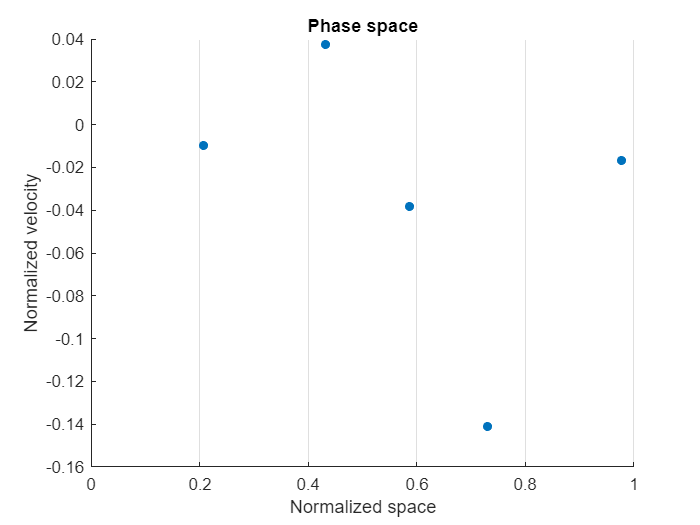

    scatter(xp1,vp1,30,'filled')

title('Phase space')
xlabel('Normalized space')
ylabel('Normalized velocity')
xlim([0 L])
xticks(space)
ax = gca;
ax.XGrid = 'on';
end